# RSN LAB 4 - Sensor Fusion

## Estimation of magnetometer calibration parameters

load("data_circl_imu.mat");
mag_x = data_circl_imu.MagField_magnetic_field_x;
mag_y = data_circl_imu.MagField_magnetic_field_y;

mag_x_trunc = mag_x(1000:end-1000);
mag_y_trunc = mag_y(1000:end-1000);

ellipse_param = fit_ellipse(mag_x_trunc, mag_y_trunc);

R1 = [ cos(ellipse_param.phi) sin(ellipse_param.phi); 
       -sin(ellipse_param.phi) cos(ellipse_param.phi) ];
    
v_line  = [[ellipse_param.X0 ellipse_param.X0]; ellipse_param.Y0 + ellipse_param.b*[-1 1] ];
h_line  = [ ellipse_param.X0+ellipse_param.a*[-1 1]; [ellipse_param.Y0 ellipse_param.Y0] ];

new_ver_line  = R1*v_line;
new_horz_line = R1*h_line;

theta_r = linspace(0,2*pi);
best_fit_ellipse_x = ellipse_param.X0 + ellipse_param.a*cos(theta_r);
best_fit_ellipse_y = ellipse_param.Y0 + ellipse_param.b*sin(theta_r);

rotated_ellipse = R1 * [best_fit_ellipse_x;best_fit_ellipse_y];

squish_factor = ellipse_param.short_axis/ellipse_param.long_axis;

R2 = [1 0 ; 0 squish_factor]; %considering minor axis as the diameter
bias = [ellipse_param.X0_in ; ellipse_param.Y0_in];

v_line_circle = R2 * R1^-1 * ([new_ver_line(1,:) - bias(1) ; new_ver_line(2,:) - bias(2)]);
h_line_circle = R2 * R1^-1 * ([new_horz_line(1,:) - bias(1) ; new_horz_line(2,:) - bias(2)]);
%-----------------------------------------------------------------------------------------------------
mag_calibrated_data = R2 * R1^-1 * [mag_x_trunc' - bias(1) ; mag_y_trunc'- bias(2)];
ellipse_to_circle = R2 * R1^-1 * [rotated_ellipse(1, :) - bias(1) ; rotated_ellipse(2, :) - bias(2)];
%-----------------------------------------------------------------------------------------------------
calibration_params = [R1 R2 bias];

## Plotting the magnetic calibration plot

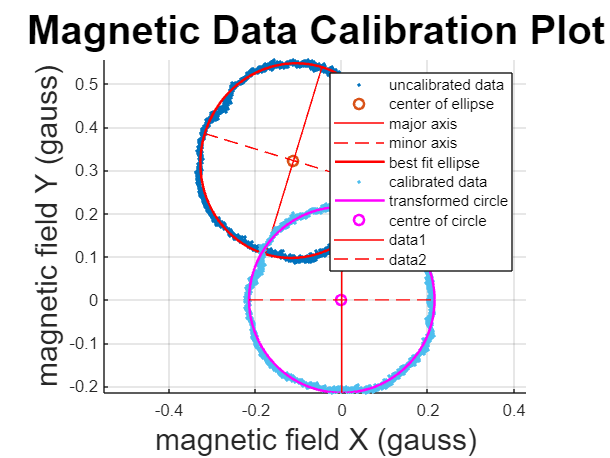

figure();
axis equal;
grid on;
hold on;

scatter(mag_x_trunc, mag_y_trunc, '.', DisplayName='uncalibrated data');
scatter(ellipse_param.X0_in, ellipse_param.Y0_in, DisplayName='center of ellipse', LineWidth=1.5);
plot(new_ver_line(1,:),new_ver_line(2,:),'r', DisplayName='major axis');
plot(new_horz_line(1,:),new_horz_line(2,:),'r',DisplayName='minor axis', LineStyle='--');
plot(rotated_ellipse(1,:),rotated_ellipse(2,:),'r', DisplayName='best fit ellipse', LineWidth=1.5);

scatter(mag_calibrated_data(1,:),mag_calibrated_data(2,:), '.', DisplayName='calibrated data');
plot(ellipse_to_circle(1,:), ellipse_to_circle(2,:), DisplayName='transformed circle', Color='magenta', LineWidth=1.5);
scatter(ellipse_param.X0_in - bias(1), ellipse_param.Y0_in - bias(2), 'magenta', DisplayName='centre of circle', LineWidth=1.5);

xlabel('magnetic field X (gauss)', FontSize=18);
ylabel('magnetic field Y (gauss)', FontSize=18);
title('Magnetic Data Calibration Plot', FontSize=24)
legend;
plot(v_line_circle(1,:),v_line_circle(2,:),'r');
plot(h_line_circle(1,:),h_line_circle(2,:),'r', LineStyle='--');
hold off;

## Time

time = data_circl_imu.Time;
time = time - min(time);
time = time(1000:end-1000);

## Yaw Correction

mag_uncalibrated_data = ([mag_x_trunc' ; mag_y_trunc']);
yaw_mag_calibrated = atan2(-mag_calibrated_data(2,:), mag_calibrated_data(1,:));
yaw_mag_uncalibrated = atan2(-mag_uncalibrated_data(2,:), mag_uncalibrated_data(1,:));

## Plotting Calibrated vs Uncalibrated Yaw from Magnetometer

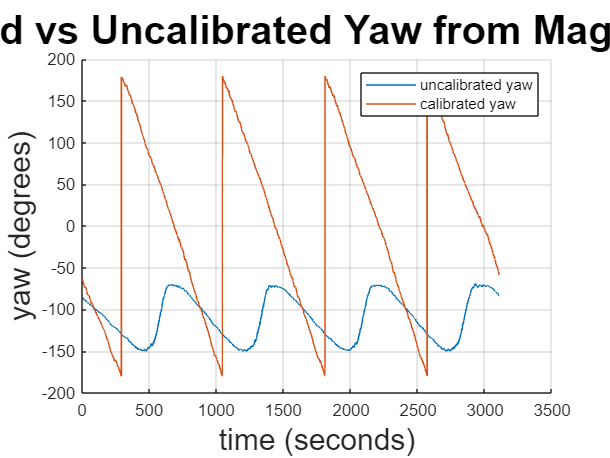

figure;
hold on;
grid on;
plot(rad2deg(yaw_mag_uncalibrated), DisplayName='uncalibrated yaw');
plot(rad2deg(yaw_mag_calibrated), DisplayName='calibrated yaw');
xlabel('time (seconds)', FontSize=18);
ylabel('yaw (degrees)', FontSize=18);
title('Calibrated vs Uncalibrated Yaw from Magnetometer', FontSize=24);
legend;
hold off;

## Converting Yaw to -180 to 180 to compare with IMU

% for i=1:numel(mag_calibrated_data(2,:))
%     if(mag_calibrated_data(2,i) > 0)
%         yaw_mag_calibrated(i) = yaw_mag_calibrated(i)*-1;
%     end 
% end

%converting yaw from radians to degree
yaw_mag_calibrated = rad2deg(yaw_mag_calibrated);

euler_angles = quat2eul([data_circl_imu.IMU_orientation_w data_circl_imu.IMU_orientation_x ...
                         data_circl_imu.IMU_orientation_y data_circl_imu.IMU_orientation_z]);
yaw_from_imu = euler_angles(:,1);

%truncating and converting yaw from radians to degree
yaw_from_imu = rad2deg(yaw_from_imu(1000:end-1000));

## Plotting Calibrated vs Uncalibrated Yaw from Magnetometer

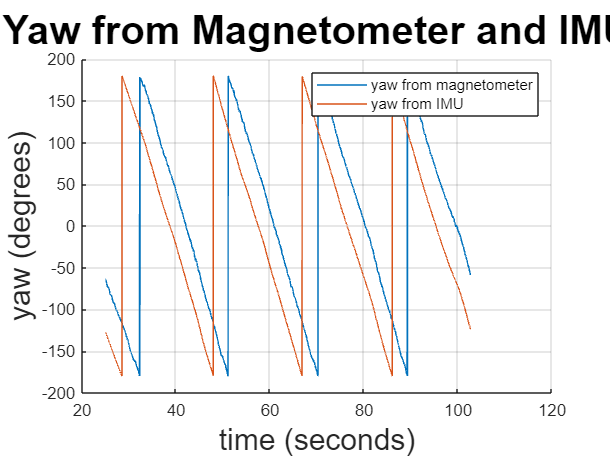

figure;
hold on;
grid on;
plot(time, (yaw_mag_calibrated), DisplayName='yaw from magnetometer');
plot(time, (yaw_from_imu), DisplayName='yaw from IMU');
xlabel('time (seconds)', FontSize=18);
ylabel('yaw (degrees)', FontSize=18);
title('Yaw from Magnetometer and IMU', FontSize=24);
legend;
hold off;

## Integrating gyro Z for yaw

gyro_z = data_circl_imu.IMU_angular_velocity_z;
gyro_z_trunc = gyro_z(1000:end-1000);

ts = 1/40;
gyro_integrated = rad2deg(cumsum(gyro_z_trunc) * ts);

% for i = 1:numel(gyro_integrated)
%     if(gyro_integrated(i) < -180)
%             gyro_integrated(i:end) = (gyro_integrated(i:end) + 360);
%     end
% end
yaw_from_gyro = gyro_integrated;

## Plotting Yaw from Magnetometer, Gyroscope and IMU

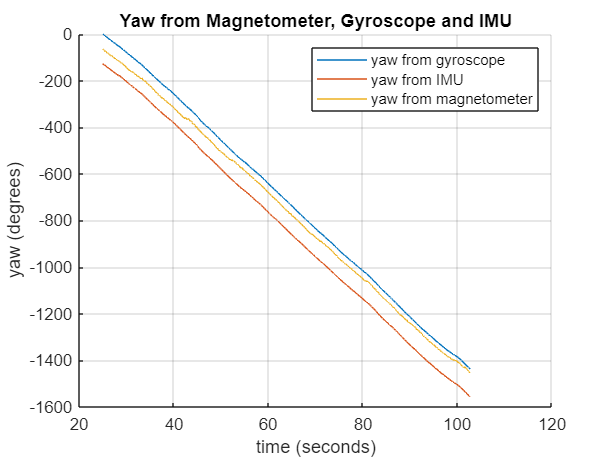

figure;
hold on;
grid on;
plot(time, yaw_from_gyro, DisplayName='yaw from gyroscope');
plot(time, unwrap(yaw_from_imu), DisplayName='yaw from IMU');
plot(time, unwrap(yaw_mag_calibrated), DisplayName='yaw from magnetometer');
xlabel('time (seconds)');
ylabel('yaw (degrees)');
title('Yaw from Magnetometer, Gyroscope and IMU');
legend;
hold off;

## Complementary Filter design

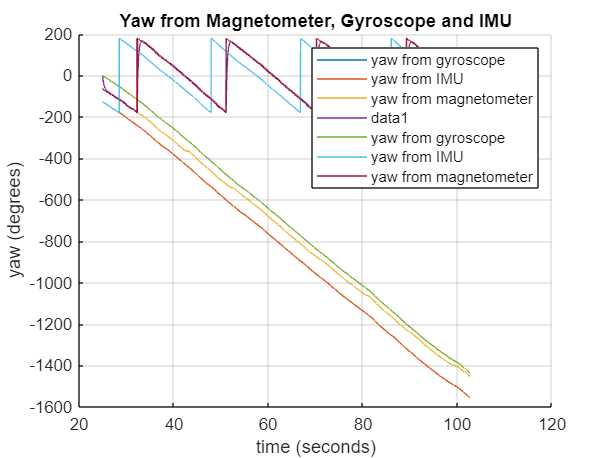

yaw_from_filter = zeros(size(gyro_z_trunc));
factor = 0.1;
for i = 2:numel(gyro_z_trunc)
    yaw_from_filter(i) = yaw_mag_calibrated(i) * factor + ...
                         (1 - factor)*(gyro_z_trunc(i)*ts + yaw_from_filter(i-1));
end
hold on;
plot(time, yaw_from_filter);
plot(time, yaw_from_gyro, DisplayName='yaw from gyroscope');
plot(time, yaw_from_imu, DisplayName='yaw from IMU');
plot(time, yaw_mag_calibrated, DisplayName='yaw from magnetometer');
xlabel('time (seconds)');
ylabel('yaw (degrees)');
title('Yaw from Magnetometer, Gyroscope and IMU');

legend;